clear;clc

## 系统参数

m = 3; % 待隔振载荷 Kg ？
M = 1.34; % 电磁吸振器的总质量 Kg 来自图片参数
k_M = 45; % 来自要求文件
          % 电磁吸振器的电—力常数 N/A
          % 线圈式均匀磁场　km = F/I = NBL  N导线圈数；Ｌ应为缠绕的半径？；Ｂ为磁场强度
L = 0.0045; % 线圈的电感　来自图片参数
c = 0.1; % 电磁吸振器的阻尼 ？
k = 34000; % 系统主弹簧刚度 ？
k_E = 30; % 作动器反电动势系数 来自图片参数
R = 5; % 线圈及导线的总电阻 来自图片参数

%% 状态空间方程建立

A = [0      1       0;
    -k/m   -c/m     k_M/m;
     0     -k_E/L  -R/L];
B = [0 0 1/L]';
C = [-k/m -c/m k_M/m];
D = 0;
E = [0      0;
     c/m    k/m;
     k_E/L  0];
system = ss(A,B,C,D);

## 开环系统伯德图

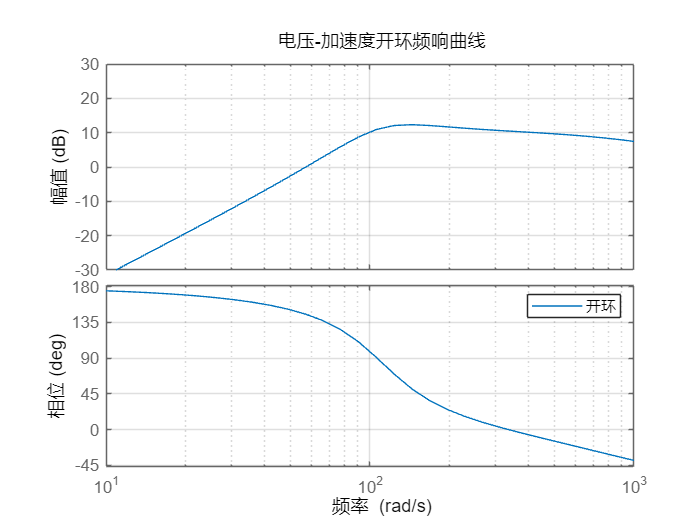

figure
bode(system); % 绘制伯德图

title('电压-加速度开环频响曲线')
grid on % 显示网格
h1 = gcf; % 获取当前图形句柄
% 设置频率范围（以rad/s为单位）
set(h1.Children(3), 'XLim', [10, 1000]); % 频率范围
% 设置增益范围（以分贝为单位）
set(h1.Children(3), 'YLim', [-30, 30]); % 增益范围
legend('开环') % 显示图例

## PID控制器